# Disign a IIR bandpass digital Filter

## Filter specification


wp = [1200 1700];
ws = [900 1900];
Rp = 0.14;
Rs = 58;


## Designing the analog filter


[n,wn] = buttord(wp,ws,Rp,Rs,"s");
[b,a] = butter(n,wn,"s");
filter = tf(b,a);
w_sam = 4600;
t_sam = 2*pi/w_sam;
f_sam = 1/t_sam;


## Analog filter magnitude response

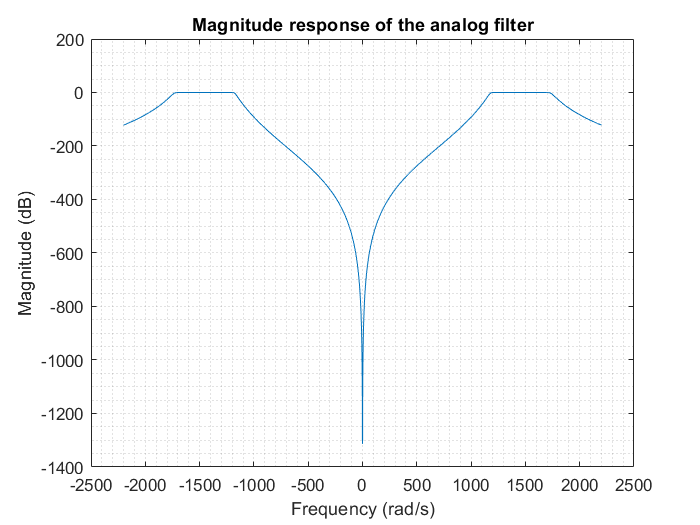

w = linspace(-2200,2200,4400);
h = freqs(b, a, w);
mag = abs(h);

figure(1)
plot(w,mag2db(mag))
title("Magnitude response of the analog filter")
xlabel("Frequency (rad/s)")
ylabel("Magnitude (dB)")
grid minor

## Prewrapping frequencies

wp(1) = 2/t_sam*tan(wp(1)*t_sam/2);
wp(2) = 2/t_sam*tan(wp(2)*t_sam/2);
ws(1) = 2/t_sam*tan(ws(1)*t_sam/2);
ws(2) = 2/t_sam*tan(ws(2)*t_sam/2);


## Frequancy Normalizing

wp = [wp(1)/(w_sam/2) wp(2)/(w_sam/2)];
ws = [ws(1)/(w_sam/2) ws(2)/(w_sam/2)];

## Transforming to a Digital filter

[n,wc] = buttord(wp,ws,Rp,Rs,'s');
disp(n)

    11



[z,p,k] = buttap(n);
[A,B,C,D] = zp2ss(z,p,k);
[At,Bt,Ct,Dt] = lp2bp(A,B,C,D,sqrt(wp(1)*wp(2)),wp(2)-wp(1));

w=linspace(-2200/(w_sam/2),2200/(w_sam/2),4400);
[Ad,Bd,Cd,Dd] = bilinear(At,Bt,Ct,Dt,1/pi); % Bilinear Transformation here
filter = ss2sos(Ad,Bd,Cd,Dd);
[b,a] = sos2tf(filter);

filter = tf(b,a); % Coefficients of the transfer function
[num,den] = tfdata(filter);
num

num = 1×1 cell array
    {[9.7337e-07 -7.0003e-17 -1.0707e-05 -7.8852e-16 5.3535e-05 -3.1071e-15 -1.6061e-04 -5.9745e-15 3.2121e-04 -6.2022e-15 -4.4970e-04 -3.4011e-15 4.4970e-04 -6.8858e-16 -3.2121e-04 2.1651e-16 1.6061e-04 1.4207e-16 -5.3535e-05 2.1361e-17 1.0707e-05 4.1929e-19 -9.7337e-07]}


den

den = 1×1 cell array
    {[1 7.2748 30.3821 90.0473 209.2506 399.5753 646.5323 902.9116 1.1027e+03 1.1874e+03 1.1336e+03 962.2256 726.9319 488.1126 290.4228 152.2125 69.6833 27.4954 9.1799 2.5148 0.5398 0.0822 0.0073]}


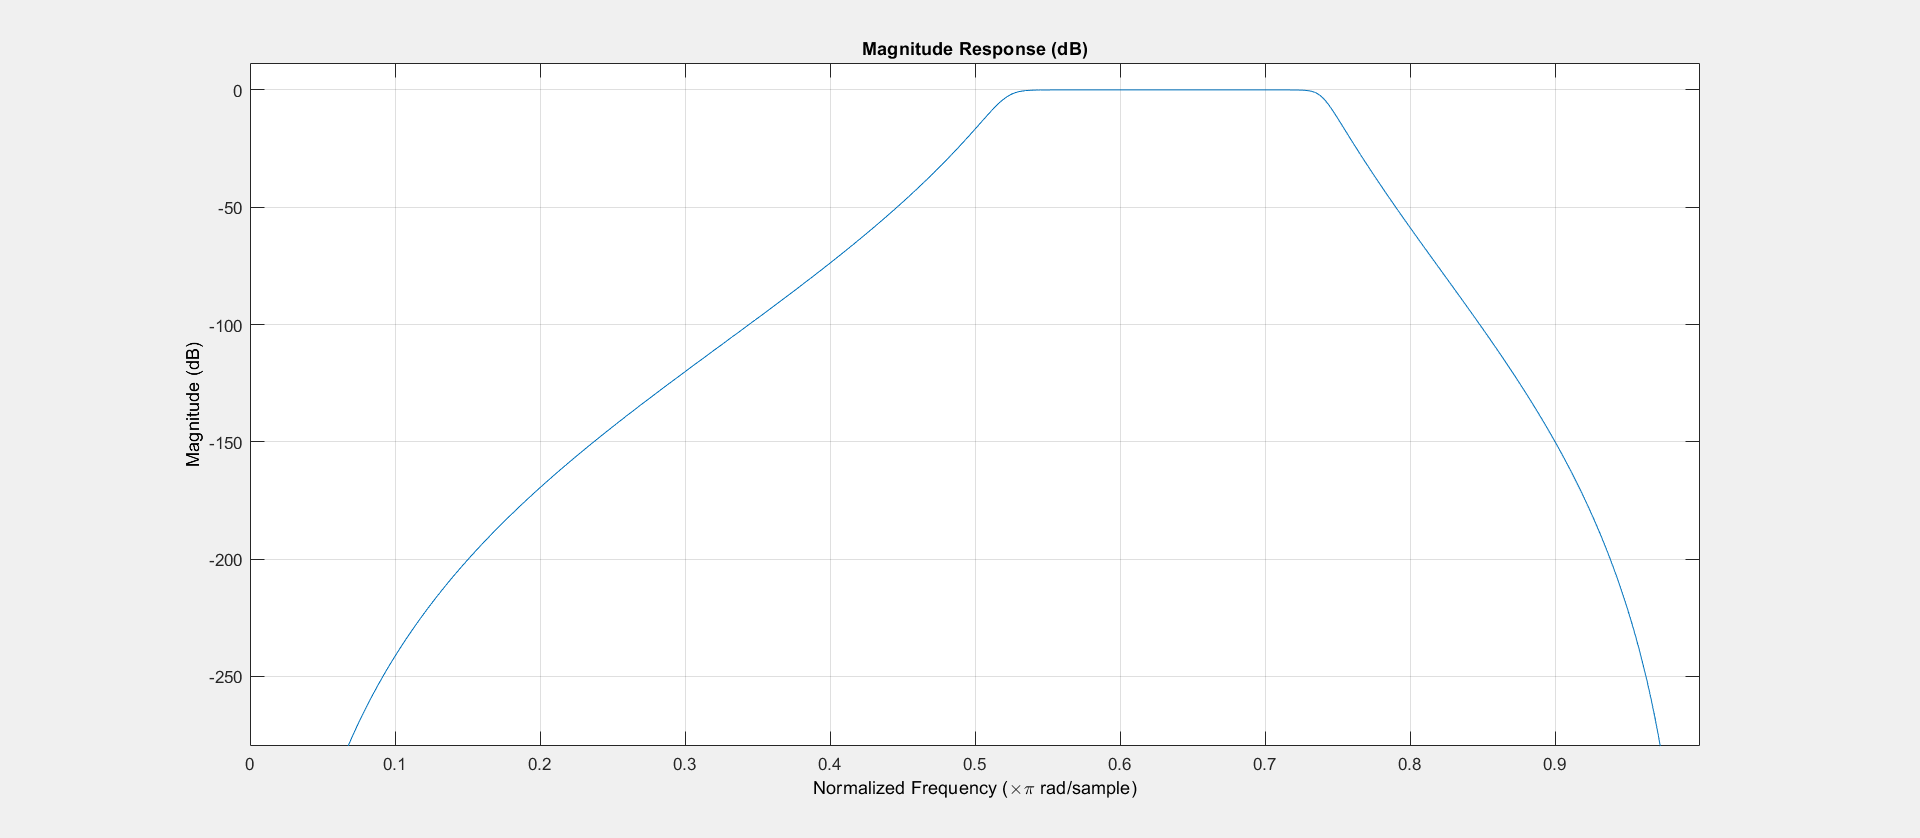

fvtool(b,a);

filtord(b,a)

ans = 22

[hd,f] = freqz(b,a,w,2);


## Digital filter magnitude response

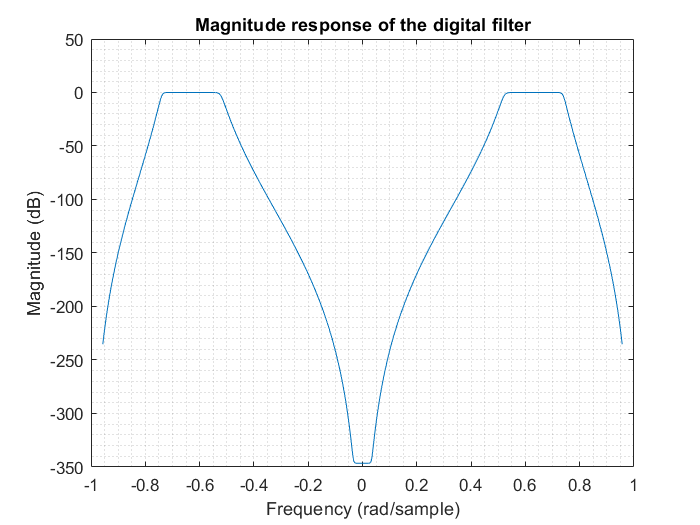

magn = abs(hd);
wp=[1200/(w_sam/2) 1700/(w_sam/2)]; 
ws=[900/(w_sam/2) 1900/(w_sam/2)];
figure(2)

plot(w,mag2db(magn))
title("Magnitude response of the digital filter")
xlabel("Frequency (rad/sample)")
ylabel("Magnitude (dB)")
grid minor

## Magnitude response of the passband

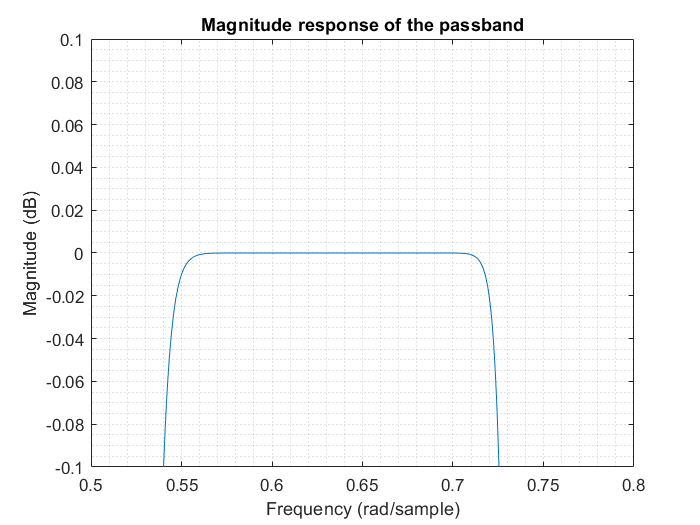


figure(3)
plot(w,mag2db(magn))
axis ([ 0.5 , 0.8 , -0.1 , 0.1]);
title("Magnitude response of the passband")
xlabel("Frequency (rad/sample)")
ylabel("Magnitude (dB)")
grid("minor")